Problem 6:

eta = 0:0.1:100;
PFA = 1 - normcdf(0.5 + log(eta));
P_Miss = normcdf(-0.5 + log(eta));

plot(PFA,P_Miss)

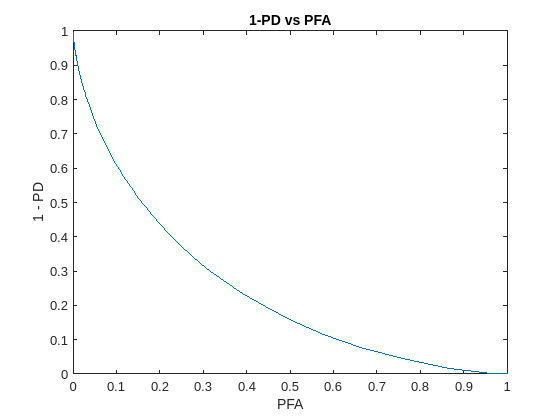

xlabel("PFA")
ylabel("1 - PD")
title("1-PD vs PFA")

problem 7

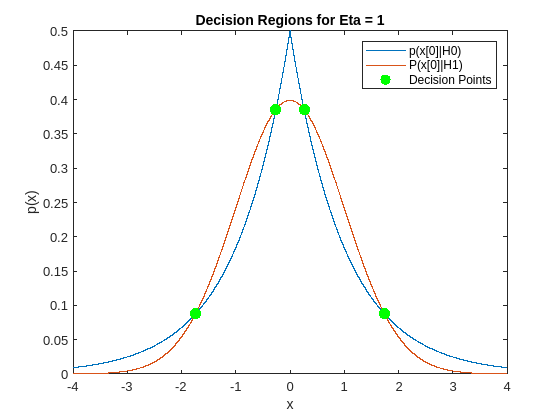

clear;
clf;
x = -4:0.001:4;
x_h0 = 0.5 * exp(-1 * abs(x));
x_h1 = (1/sqrt(2*pi)) * exp(-0.5 * x.^(2));
plot(x,x_h0,x,x_h1)
xlabel("x")
ylabel("p(x)")
hold on

%plot the eta points
eta = 1;
x_ns = zeros(1,4);

x_ns(1) = -1 - sqrt(1 - 2 * log(eta * sqrt(2 * pi)/2));
x_ns(2) = -1 + sqrt(1 - 2 * log(eta * sqrt(2 * pi)/2));
x_ns(3) = +1 - sqrt(1 - 2 * log(eta * sqrt(2 * pi)/2));
x_ns(4) = +1 + sqrt(1 - 2 * log(eta * sqrt(2 * pi)/2));

%compute p_x_ns
p_x_ns = 0.5 * exp(-1 * abs(x_ns));
plot(x_ns,p_x_ns,".","MarkerSize",30,"Color","green");
legend("p(x[0]|H0)","P(x[0]|H1)","Decision Points")
title("Decision Regions for Eta = 1")